# NMOS FET Solver

#### Chris Bonney

FET is in saturation


Id = 2.128 mA


Vds = 2.616 V


Vgs = 2.188 V


Vov = 0.1883 V


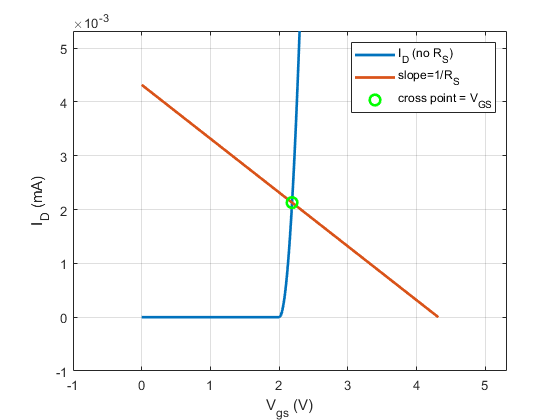

electronics_helper


kn = 120*m;
Vt = 2;
Vcc = 9;
Vcc = 9;
RG1 = 51*k ;
RG2 = 47*k;
RD = 2*k;
RS = 1*k;

% check if cutoff
Vgs = Vcc*RG2/(RG1+RG2);

cutoff = Vgs < Vt;
if cutoff
    disp('FET is in cutoff')
    return
end

Vov = Vgs - Vt;

% guess saturation
Id = kn*Vov^2/2;
Vds = Vdd - Id*RD;
if Vds >= Vov && RS == 0
    disp('FET is in saturation')
    disp(sprintf('Id = %2.3g mA',Id/m))
    disp(sprintf('Vd = %2.3g V',Vds))
    disp(sprintf('Vgs = %2.3g V',Vgs))
    disp(sprintf('Vov = %2.3g V',Vov))
    return
end

if RS == 0
    syms vds
    ids = @(vds) kn*(Vov - vds/2)*vds;
    sol = solve(vds == 9 - ids(vds)*RD);
    for ii = 1:2
        Vds = vpa(sol(ii));
        if (Vds <= Vov)
            Id = ids(Vds);
            disp('FET is in triode')
            disp(sprintf('Id = %2.3g mA',ids(Vds)/m))
            disp(sprintf('Vd = %2.3g V',Vds))
            disp(sprintf('Vov = %2.3g V',Vov))
            return
        end
    end
    disp('error in calculations')
    return
end

if RS ~= 0
    VG = Vgs;
    Id = @(Vgs) (kn*(Vgs-Vt).^2/2);
    Rinv = @(v) (-v+VG)./Rs;

    figure
    fplot(@(v) Id(v).*(v>=Vt),[0,VG],'LineWidth',2)
    hold on
    grid on
    fplot(Rinv,[0,VG],'LineWidth',2)
    xlim([-1,VG+1])
    ylim([-1*m,Rinv(0)+1*m])
    xlabel('V_{gs} (V)')
    ylabel('I_{D} (mA)')

    syms v
    VGS = max(vpa(solve(Rinv(v)==Id(v))));
    plot(VGS,Id(VGS),'go','LineWidth',2,'MarkerSize',8)
    
    Vov = VGS - Vt;
    Id = Id(VGS);
    Vds = Vdd - Id*(RD+RS);
    
    if Vds >= Vov
        disp('FET is in saturation')
        disp(sprintf('Id = %3.4g mA',Id/m))
        disp(sprintf('Vds = %3.4g V',Vdd-Id*(RD+RS)))
        disp(sprintf('Vgs = %3.4g V',VGS))
        disp(sprintf('Vov = %3.4g V',Vov))
    else 
        disp('FET is probably triode???')
    end
        
    legend({'I_D (no R_S)','slope=1/R_S','cross point = V_{GS}'})
    return
    
end


disp('error in calculations')